a = 8; b = 0; c = 5; d = 10;
t_1 = -1; t_2 = 4;
T = 20;
dt = 0.1;

t = -T/2 : dt : T/2;
signal = zeros(size(t));

signal(t_1 <= t & t <= t_2) = a;

noisy_signal = signal + b*(rand(size(t)) - 0.5) + c*sin(d*t);

v = 0 : 1/T : 1/dt;

T = 0.8;

linear_numerator = 1;
linear_denominator = [T, 1];

linear_filter = tf(linear_numerator, linear_denominator);
linear_filtered_signal = lsim(linear_filter, noisy_signal, t);

signal_fourier = fftshift(fft(noisy_signal));
linear_filtered_fourier = fftshift(fft(linear_filtered_signal));

[linear_h, linear_w] = freqresp(linear_filter, v);

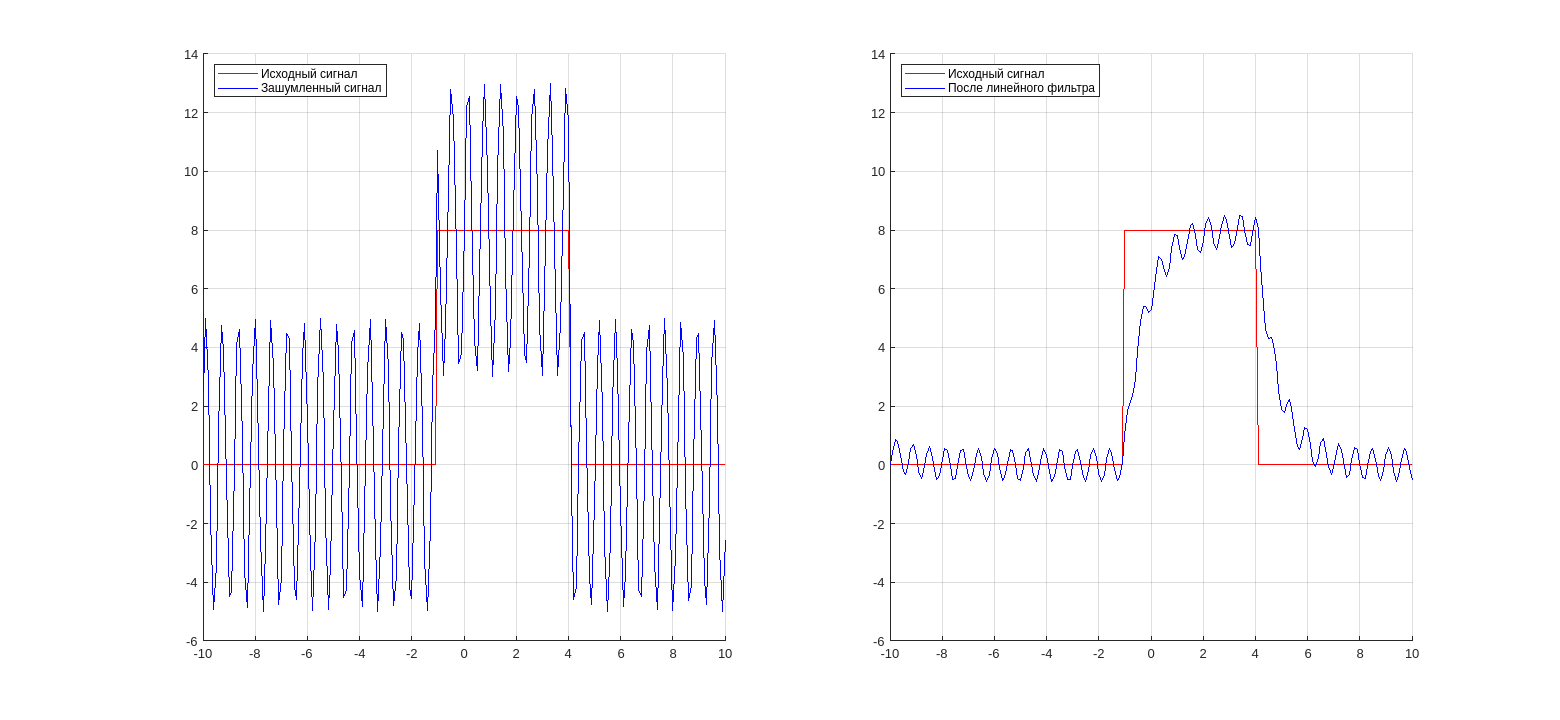

figure;
ax1 = subplot(1, 2, 1);
hold on;
plot(t, signal, 'r');
plot(t, noisy_signal, 'b');
hold off;
legend({"Исходный сигнал", "Зашумленный сигнал"}, 'Location', 'northwest');
grid on;

ax2 = subplot(1, 2, 2);
hold on;
plot(t, signal, 'r');
plot(t, linear_filtered_signal, 'b');
hold off;
legend({'Исходный сигнал', "После линейного фильтра"}, 'Location', 'northwest');
grid on;

linkaxes([ax1, ax2]);
pos = get(gcf, 'Position');
set(gcf, 'Position', pos + [-1000 -300 1000 300]);

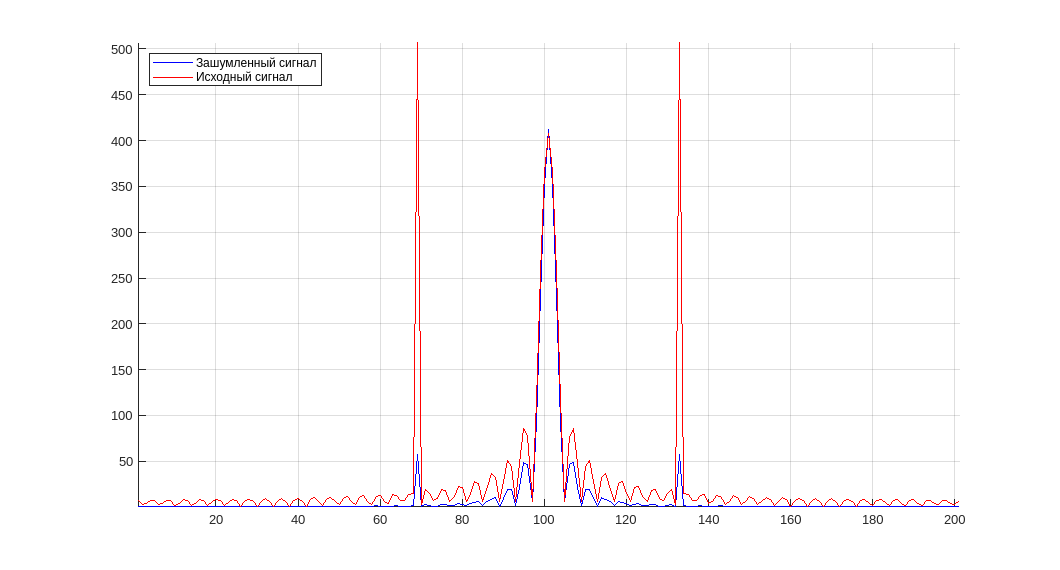

figure;
hold on;
plot(abs(linear_filtered_fourier), 'b');
plot(abs(signal_fourier), 'r');
hold off;
legend({"Зашумленный сигнал", "Исходный сигнал"}, 'Location', 'northwest');
axis('tight');
grid on;

pos = get(gcf, 'Position');
set(gcf, 'Position', pos + [-500 -150 500 150]);    

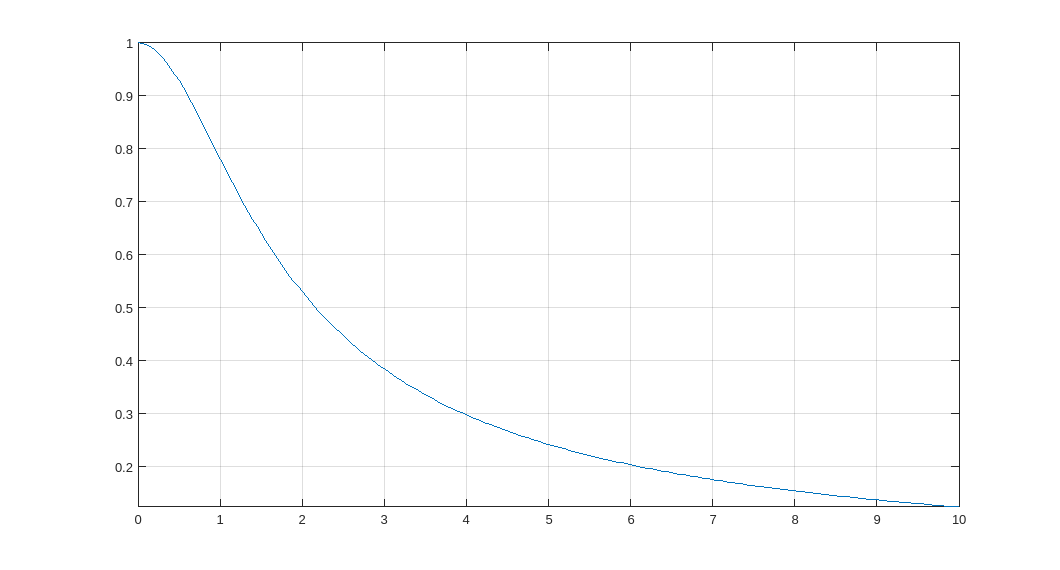

figure;
plot(linear_w, abs(squeeze(linear_h)));
axis('tight');
grid on;

pos = get(gcf, 'Position');
set(gcf, 'Position', pos + [-500 -150 500 150]);

T1 = 0.1; T2 = 0.7; T3 = 0.5;

nonlinear_numerator = [T1^2, 2*T1, 1];
nonlinear_denominator = [T2 * T3, T2 + T3, 1];

nonlinear_filter = tf(nonlinear_numerator, nonlinear_denominator);
nonlinear_filtered_signal = lsim(nonlinear_filter, noisy_signal, t);

nonlinear_filtered_fourier = fftshift(fft(nonlinear_filtered_signal));

[nonlinear_h, nonlinear_w] = freqresp(nonlinear_filter, v);
nonlinear_h = squeeze(nonlinear_h);

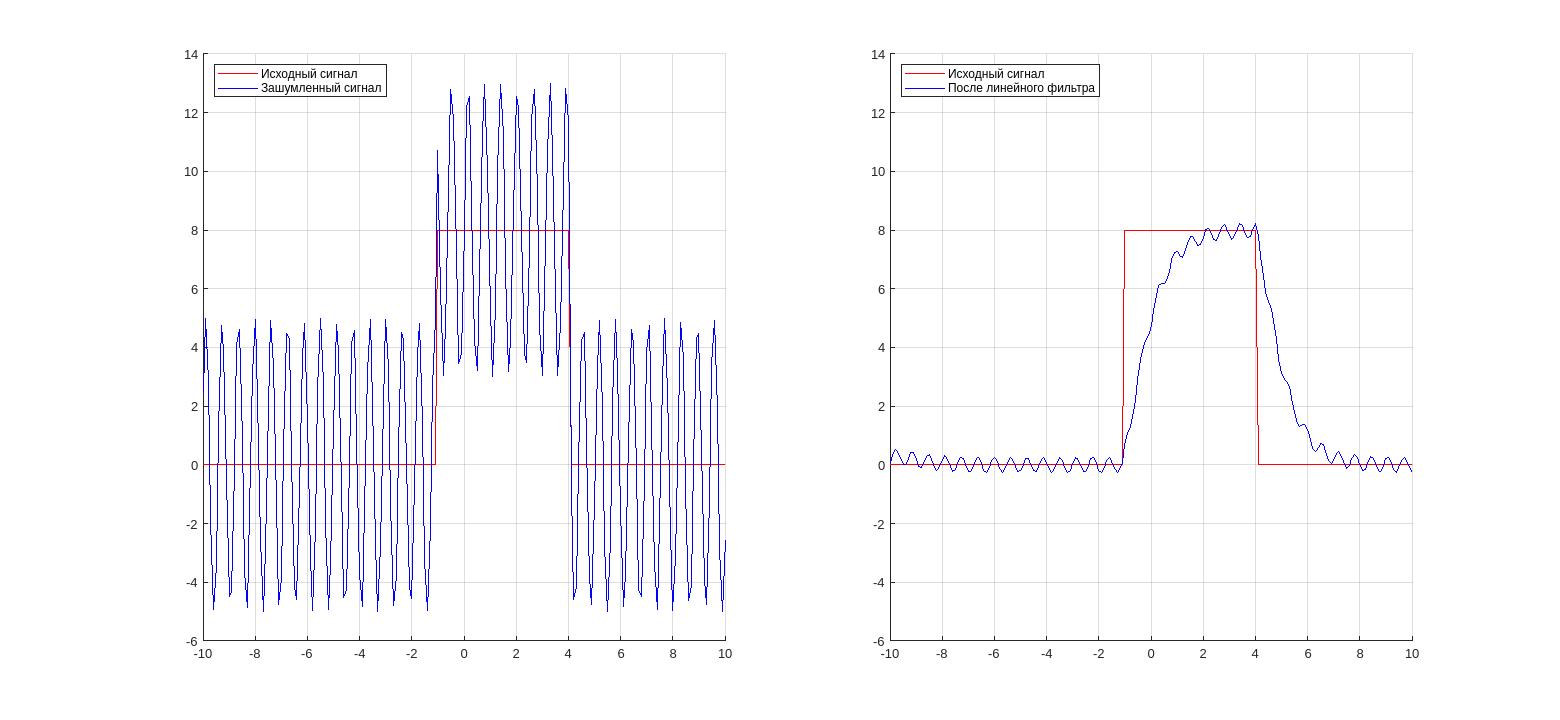

figure;
ax1 = subplot(1, 2, 1);
hold on;
plot(t, signal, 'r');
plot(t, noisy_signal, 'b');
hold off;
legend({"Исходный сигнал", "Зашумленный сигнал"}, 'Location', 'northwest');
grid on;

ax2 = subplot(1, 2, 2);
hold on;
plot(t, signal, 'r');
plot(t, nonlinear_filtered_signal, 'b');
hold off;
legend({'Исходный сигнал', "После линейного фильтра"}, 'Location', 'northwest');
grid on;

linkaxes([ax1, ax2]);
pos = get(gcf, 'Position');
set(gcf, 'Position', pos + [-1000 -300 1000 300]);

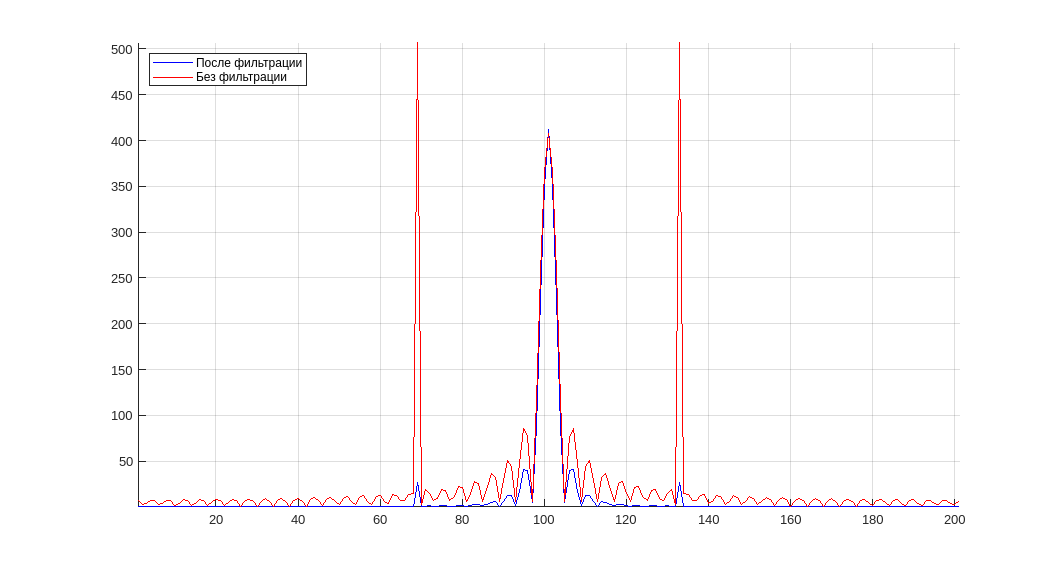

figure;
hold on;
plot(abs(nonlinear_filtered_fourier), 'b');
plot(abs(signal_fourier), 'r');
hold off;
legend({"После фильтрации", "Без фильтрации"}, 'Location', 'northwest');
axis('tight');
grid on;

pos = get(gcf, 'Position');
set(gcf, 'Position', pos + [-500 -150 500 150]);

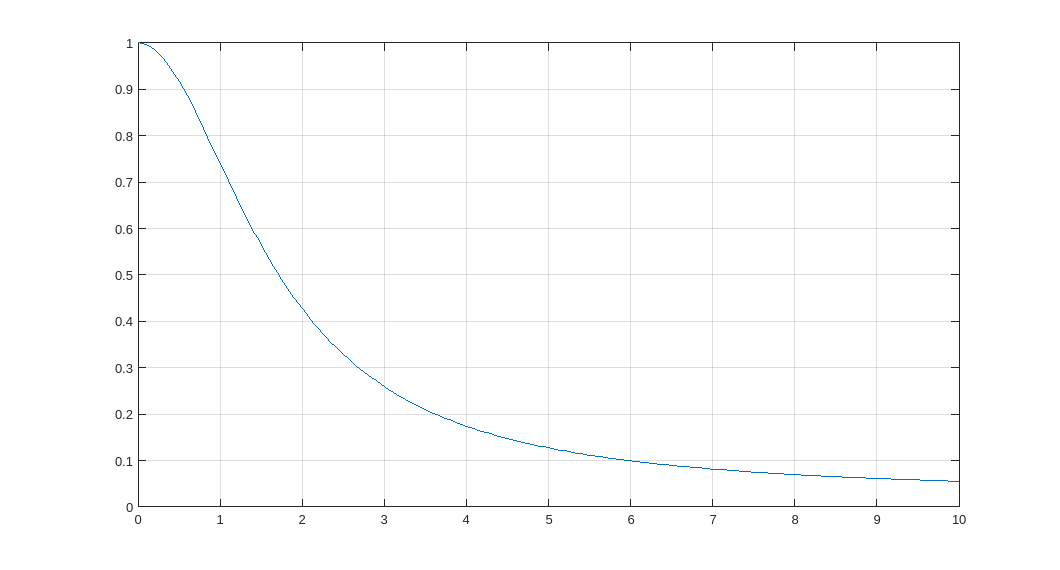

figure;
plot(nonlinear_w, abs(nonlinear_h));
xlim('tight');
ylim([0, 1]);
grid on;

pos = get(gcf, 'Position');
set(gcf, 'Position', pos + [-500 -150 500 150]);